### Support Vector Machine

Fit a support vector machine for binary classification on the response variable.

An SVM classifies data by finding the best hyperplane that separates all data points of one class from those of the other class. The *best* hyperplane for an SVM means the one with the largest *margin* between the two classes. Margin means the maximal width of the slab parallel to the hyperplane that has no interior data points.

The *support vectors* are the data points that are closest to the separating hyperplane; these points are on the boundary of the slab. The following figure illustrates these definitions, with + indicating data points of type 1, and – indicating data points of type –1.

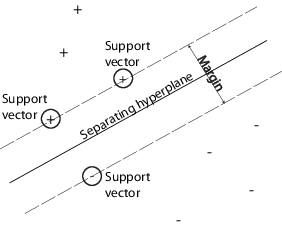

Select SVM training parameters

standardize = true;
kernel = 'linear';
removeDups = false;

Expected proportion of outliers in training data

outlierFraction = 0;

Train the model

mdl = fitcsvm(binnedFeatures,responseVar,...
    'PredictorNames',predictorVars,...
    'Standardize',standardize,...
    'KernelFunction',kernel,...
    'OutlierFraction',outlierFraction,...
    'RemoveDuplicates',removeDups)

Extract scores from the model

[~,scores] = predict(mdl,binnedFeatures);
scores = scores(:,2); % Second class